# Question-1)

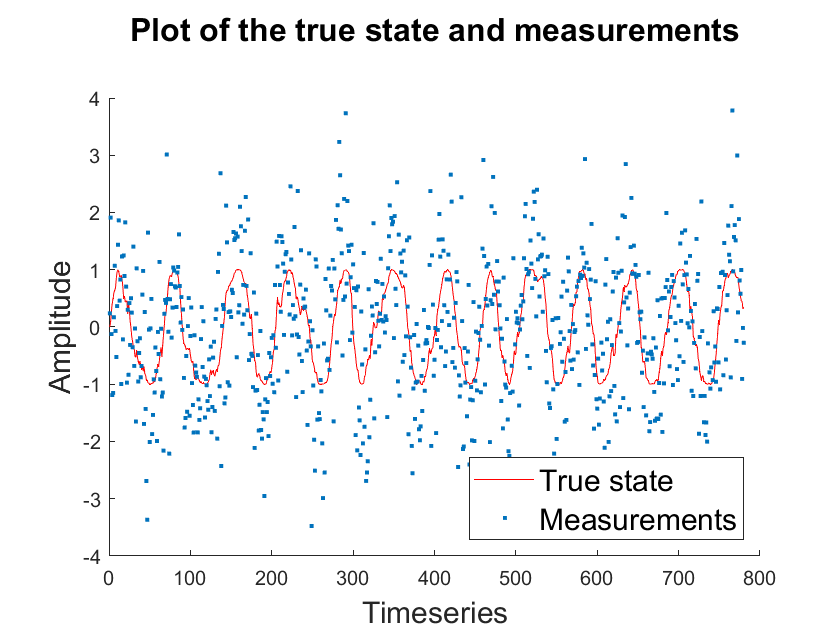

clc;
clear;

% Loading the data in matlab
data = load("sin-data.txt");
true_state = data(:,1);
measurements = data(:,2);

% Assuming the data is recorded after every 1 seconds
timeseries = [1:1:numel(measurements)];

% Plotting the raw data 
figure
hold on
plot(timeseries, true_state,'Color',[1 0 0])
scatter(timeseries, measurements,'.','MarkerEdgeColor',[0 0.4470 0.7410])
legend('True state', 'Measurements','FontSize',15,location='southeast')
hold off
title('Plot of the true state and measurements','    ',FontSize=16)
xlabel('Timeseries',FontSize=15)
ylabel('Amplitude',FontSize=15)


syms T x xdot h d h n a 

% State space equations
f = [x+xdot*T; 
     xdot+a; 
     sin(x/10)];

% State variables
X = [x;
     xdot;
     h];

% Observation
Y = [d];

% State observation equations
g = [h + n];

% Jacobians 
Fx = jacobian(f,X);
Gx = jacobian(g,X);
Fa = [0 0 0
      0 1 0
      0 0 0];
Gn = jacobian(g,n);

% Dynamic uncertainity matrix
Q = [0 0 0
     0 5 0
     0 0 0];

% Measurement noise covariance
R = [0.001];

% Initial variance
S = [1 0 0
     0 1 0.001
     0 0.001 1];

% Number of state variables and randoms
n_states = 3; 
a = rand(1);
n = rand(1);
T = 1;

% Measurements
Y =  measurements; 

% Inital states
h = measurements(1,1);
x = asin(h)*10;
xdot=x/T;
fx = double(subs(f));
Fa = double(subs(Fa));
Gn = double(subs(Gn));

% Estimates matrix
X_est(:,1) = double(subs(X));


%% EKF loop
for i = 2:numel(measurements)
    %% State prediction
    X_pred = double(fx);
    
    %% State values
    x = double(X_pred(1));
    xdot = double(X_pred(2));
    h = double(X_pred(3));
    
    %% Updating jacobians
    Fx = double(subs(Fx));
    Gx = double(subs(Gx));

    %% State covariance prediction
    S_pred = Fx*S*Fx' + Fa*Q*Fa'; 
    
    %% Kalman gain
    K = (S_pred*Gx')/(Gx*S_pred*Gx' + Gn*R*Gn');
    
    %% Correction
    X_pred = X_pred+K*(Y(i)-h);
    S = (eye(n_states)-K*Gx)*S_pred;
    
    %% Storing estimation
    X_est(:,i) = X_pred;
end

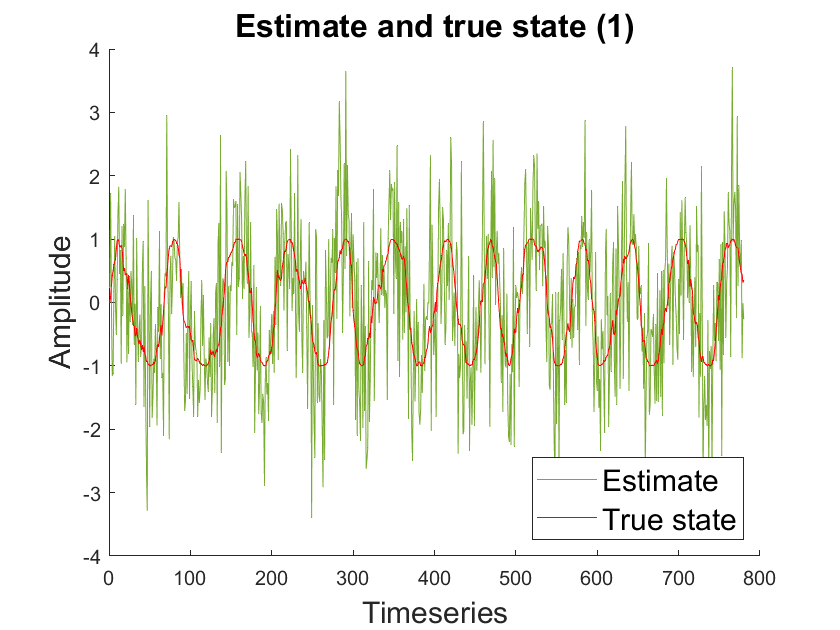


%% Plot of estimate and true state
figure
hold on
plot(X_est(3,:),Color=[0.4660 0.6740 0.1880])
plot(true_state,Color=	[1 0 0])
legend('Estimate', 'True state','FontSize',15,location='southeast')
hold off
title('Estimate and true state (1)',FontSize=16)
xlabel('Timeseries',FontSize=15)
ylabel('Amplitude',FontSize=15)